% Load the audio file
audio_path = "C:\Users\USER\OneDrive\Documents\MATLAB\PROJECT_Major\WhatsApp Audio.waptt.opus"; % Replace with the actual path to your audio file
[y, fs] = audioread(audio_path); % Read the audio file

% Autocorrelation for pitch estimation
[maxCorr, lag] = xcorr(y, 'coeff');
lag = lag / fs; % Convert lag values to time in seconds

% Find the appropriate range for pitch estimation
valid_range = lag > 0.0025 & lag < 0.02; % Typical pitch period range for human voice
pitch_period = lag(valid_range);
maxCorr = maxCorr(valid_range);

% Find the lag value corresponding to the maximum correlation for highest frequency
[~, idx_max] = min(pitch_period); % Minimizing pitch_period gives the maximum frequency

% Find the lag value corresponding to the minimum correlation for lowest frequency
[~, idx_min] = max(pitch_period); % Maximizing pitch_period gives the minimum frequency

% Calculate pitch frequency for highest and lowest frequencies
highest_pitch_period = pitch_period(idx_max);
lowest_pitch_period = pitch_period(idx_min);

highest_pitch_frequency = 1 / highest_pitch_period;
lowest_pitch_frequency = 1 / lowest_pitch_period;

% Display highest and lowest frequency values
disp(['Highest Frequency: ', num2str(highest_pitch_frequency), ' Hz']);

Highest Frequency: 390.2439 Hz


disp(['Lowest Frequency: ', num2str(lowest_pitch_frequency), ' Hz']);

Lowest Frequency: 50.1567 Hz


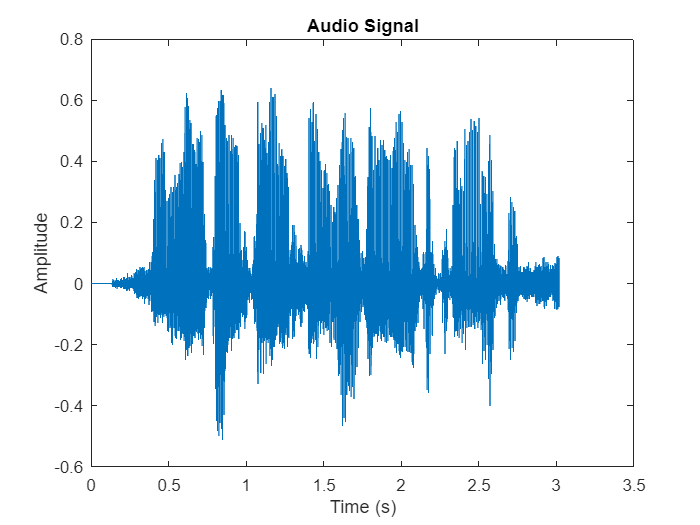


% Time axis for plotting
time = (0:length(y) - 1) / fs;

% Plot the signal
figure;
plot(time, y);
title('Audio Signal');
xlabel('Time (s)');
ylabel('Amplitude');

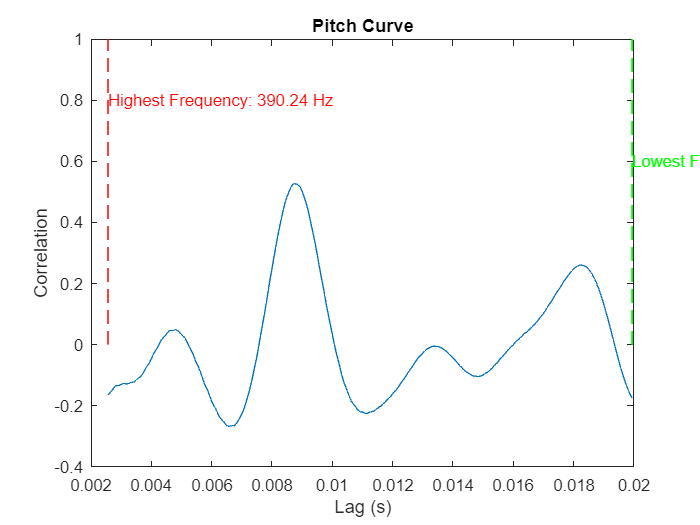


% Plot the pitch curve
figure;
plot(lag(valid_range), maxCorr);
hold on;

% Highlight the highest and lowest frequencies
highest_freq_lag = pitch_period(idx_max);
lowest_freq_lag = pitch_period(idx_min);
plot([highest_freq_lag, highest_freq_lag], [0, 1], 'r--', 'LineWidth', 1);
plot([lowest_freq_lag, lowest_freq_lag], [0, 1], 'g--', 'LineWidth', 1);

% Display highest and lowest frequency values as text annotations
text(highest_freq_lag, 0.8, ['Highest Frequency: ', num2str(highest_pitch_frequency, '%.2f'), ' Hz'], 'Color', 'r');
text(lowest_freq_lag, 0.6, ['Lowest Frequency: ', num2str(lowest_pitch_frequency, '%.2f'), ' Hz'], 'Color', 'g');

title('Pitch Curve');
xlabel('Lag (s)');
ylabel('Correlation');

hold off;